# **drawSupport**

Draw a beam support

## Description

## Syntax

drawSupport(type,x0,y0,ht,th)

drawSupport(__,LineSpec) 

p = drawSpring(__)

## Description

## Method

## Arguments

### Input Arguments

**type - **1=fixed,2=simple

**x0, y0  **--- base point (bottom, center)

** ht      **---  height

** rot  ** --- support inclination angle in deg (0, default)

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk,p.yk -- key points

- p.color - line color

## Examples

### Example 1

drawInit
x0 = 0; y0=0; r=1;ht=1;th=-30

th = -30

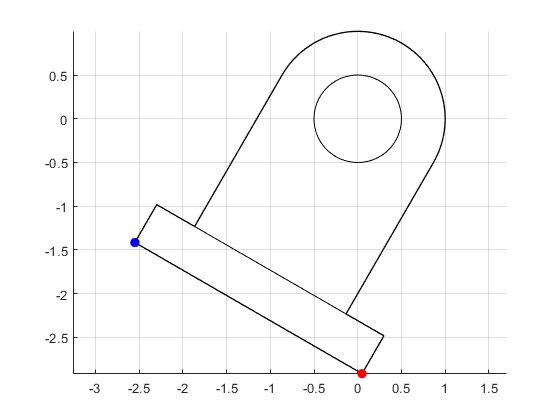

p = drawSupport(1,r,x0,y0,th,'b');
scatter(p.xk(1),p.yk(1),50,'b','filled')
scatter(p.xk(2),p.yk(2),50,'r','filled')
grid on

### Example 2

drawInit
x0 = 0; y0=0; r=1;ht=1;th=-30

th = -30

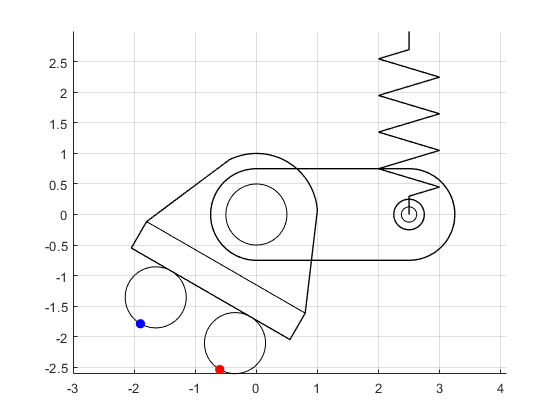

p = drawSupport(2,r,x0,y0,th,'b');
c=drawCanoe(4,1.5,0,0,0,'-pos',4);
drawSpring(c.xk(6),c.yk(6),0.5,3,4,90,'-type','ext')
drawDonut(0.5,0.25,c.xk(6),c.yk(6))
scatter(p.xk(1),p.yk(1),50,'b','filled')
scatter(p.xk(2),p.yk(2),50,'r','filled')
grid on

## **See Also**

## References